## 0. Setting parameters 

clear;close all;
FILE_NAME_BKGD = 'Aug4-0kg-step0.01MeV-nml';
FILE_NAME_SMPL = 'P13-1kg-step0.01MeV-nml';
ENERGY_AXIS = [0.01:0.01:12]';
OUTLIER_THRESHOLD = 3; % times of variance out which the dots are regard as outlier
ACC_STABLE_TIMESTAMP = 150;

ROI.Cl35a = [195-15,195+15]; % Channel in normalized spectrum
ROI.Cl35b = [611-15,611+15];
ROI.Cl35c = [662-15,662+15];
ROI_TITLE.Cl35a = '1.959MeV';
ROI_TITLE.Cl35b = '6.111MeV';
ROI_TITLE.Cl35c = '6.620MeV';

ROI_SELECTED = {'Cl35b','Cl35c'};

% Keep ROIs in ROI_SELECTED
nameTmp = fieldnames(ROI);
for i = 1:length(nameTmp)
    if ~ismember(nameTmp{i},ROI_SELECTED)
        ROI = rmfield(ROI,nameTmp{i});
        ROI_TITLE = rmfield(ROI_TITLE,nameTmp{i});
    end
end
ROI = orderfields(ROI);
ROI_TITLE = orderfields(ROI_TITLE);
ROI_NAMES = fieldnames(ROI_TITLE);
TEST_DETECTION_TIME = [1,2,5,10,30]; % Unit: detection time of one ".spe" file
TEST_DETECTION_TIME = 1:30;
N_ROC_POINT = 500;

## 1. Import data and data pre-processing 

### 1.1 Import

bkgd = loadnormalizedseq(FILE_NAME_BKGD);
if isequal(bkgd,-1)
    error('Error: Normalized background file can not be read');
end
smpl = loadnormalizedseq(FILE_NAME_SMPL);
if isequal(smpl,1)
    error('Error: Normalized sample file can not be read');
end

### 1.2 Pre-processing

#### 1.2.1 Delete outlier

bkgd = deleteoutlier(bkgd,ACC_STABLE_TIMESTAMP,ROI,OUTLIER_THRESHOLD,0);
smpl = deleteoutlier(smpl,ACC_STABLE_TIMESTAMP,ROI,OUTLIER_THRESHOLD,0);

#### 1.2.3 Lower channel numbers

nCh = 5;
newbkgd = [];newsmpl=[];
for i = 1:nCh:size(bkgd,1)-nCh+1
    newbkgd = [newbkgd;sum(bkgd(i:i+nCh-1,:),1)];
    newsmpl = [newsmpl;sum(smpl(i:i+nCh-1,:),1)];
end
bkgd = newbkgd;smpl = newsmpl; 
clear newbkgd newsmpl;

## 2. 全区域投影

### 3.1 计算线性投影方向

projectionVec.centers = mycenters(bkgd,smpl);
projectionVec.fisher = myfisher(bkgd,smpl); % 矩阵接近奇异值的问题 来自于 矩阵病态

Notice: Data > channel#228 is deleted since they are zero


load('lib_projVector240ch.mat');
projectionVec.fisherP21 = fisher2019aug06P21aug04t1s240chnml;
projectionVec.fisherP22 = fisher2019aug06P22aug04t1s240chnml;
projectionVec.centerP21 = centers2019aug06P21aug04t1s240chnml;
projectionVec.centerP22 = centers2019aug06P22aug04t1s240chnml;
% fff = projectionVec.fisher;
% projectionVec.fisher1eminus7 = fff.*(abs(fff)>1e-7);

### 3.2 不同投影方向效果

projectionVecNames = fieldnames(projectionVec);
for iVec = 1:length(fields(projectionVec))
    for iTime = TEST_DETECTION_TIME % Unit: detection time of one ".spe" file
        [Jrule(iTime,iVec),aucProjection(iTime,iVec)] = ...
            estimatevector(combinespectra(bkgd,iTime),combinespectra(smpl,iTime), ...
            getfield(projectionVec,projectionVecNames{iVec}));
    end
end

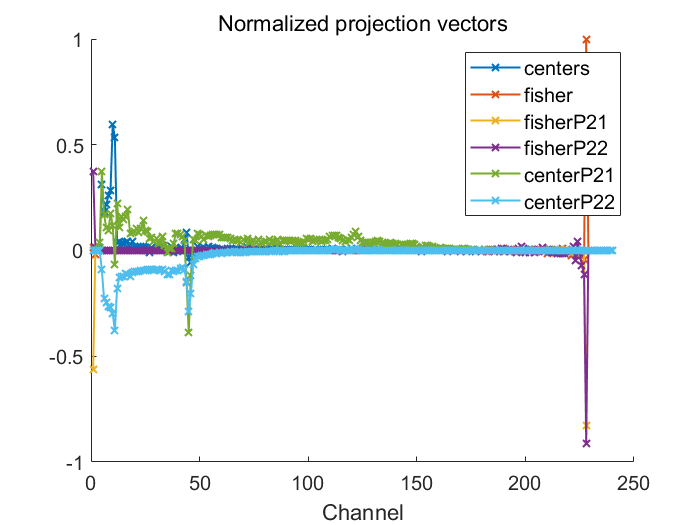

handle = plotmyvec(projectionVec,projectionVecNames);

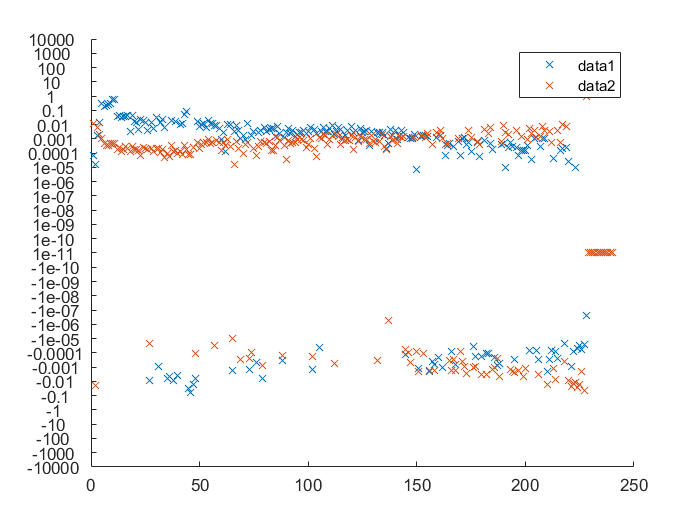

[handle,ax] = semipnlogy(1:size(projectionVec.fisher,1),[projectionVec.centers,projectionVec.fisher],1e-11);

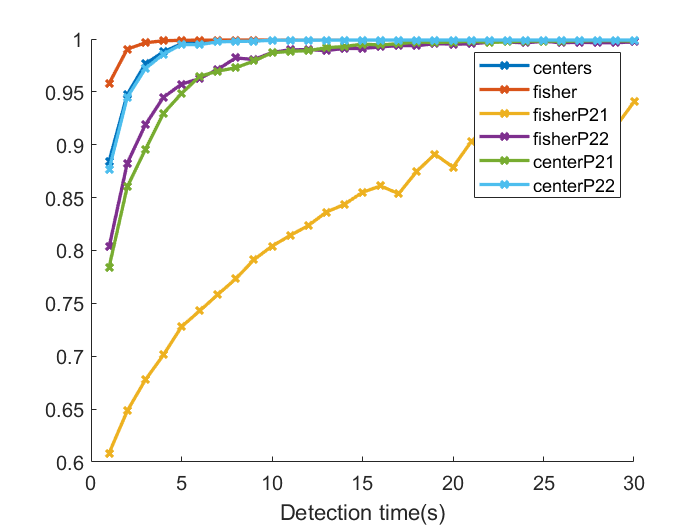

handle = plotdiscvalue(aucProjection,projectionVecNames);